# Import data from text file

## Set up the Import Options and import the data

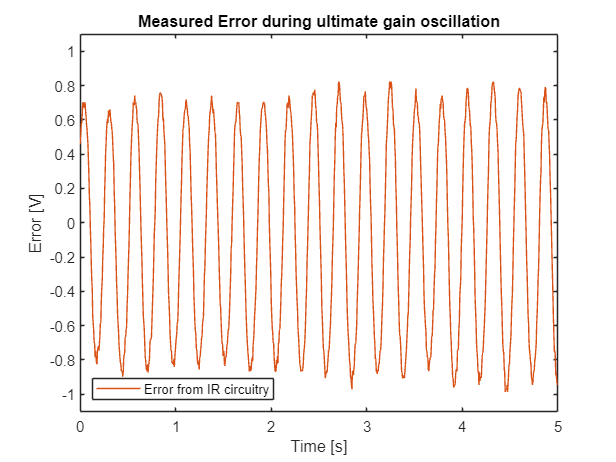

clear all;
clf;
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_vh_2.csv", opts);
scoperb62(:,"xaxis") = scoperb62(:,"xaxis")+5; % fix time
scoperb62(:,"VarName2") = scoperb62(:,"VarName2")-1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3")-1.65;

plot(scoperb62,"xaxis","VarName2",'Color',[0.8500, 0.3250, 0.0980])
hold on
%plot(scoperb62,"xaxis","VarName3")
ylabel('Error [V]')
xlabel('Time [s]')
legend({'Error from IR circuitry'},'Location','southwest')

xlim([0 5])
ylim([-1.1 1.1])
title('Measured Error during ultimate gain oscillation')
hold off

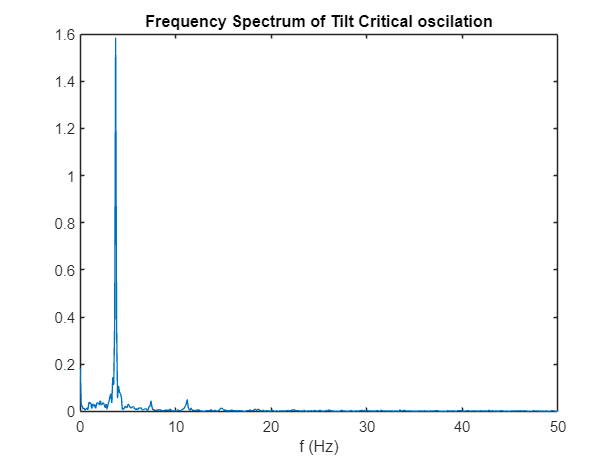

array = table2array(scoperb62(:,"VarName2"));
% Remove NaN entries
cleanedArray = array(~isnan(array));

Fs = 100;            % Sampling frequency
T = 1/Fs;             % Sampling period
L = 10*Fs;             % Length of signal

Y = fft(cleanedArray);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;

plot(f,P1)
title("Frequency Spectrum of Tilt Critical oscilation")
xlabel("f (Hz)")

## Clear temporary variables

clear all;
clf
clear opts

Fs = 100;           % Sampling frequency
T = 1/Fs;           % Sampling period
L = 10*Fs;          % Length of signal
t_s = 59;           % Encoder signal start time

# Import data from text file

## Set up the Import Options and import the data

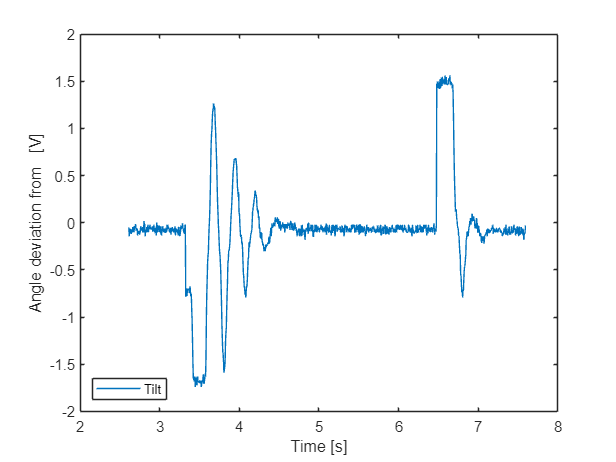

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_tilt_nopid.csv", opts);
scoperb62(:,"xaxis") = scoperb62(:,"xaxis") + 10; % fix time
scoperb62(:,"VarName2") = scoperb62(:,"VarName2") - 1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3") - 1.65;

scope_array = table2array(scoperb62);
scope_array = scope_array((scope_array(:,1) > 2.6) & (scope_array(:,1) < 7.6),:); % fix time

plot(scope_array(:,1),scope_array(:,2))
hold on
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt'},'Location','southwest')

hold off

## Clear temporary variables

clear opts
clf

opts2 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ":";

% Specify column names and types
opts2.VariableNames = ["Motor", "Encoder Position"];
opts2.VariableTypes = ["double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Import the data
motor_encoder_tilt_nopid = readtable("putty\motor_encoder_tilt_nopid.log", opts2);

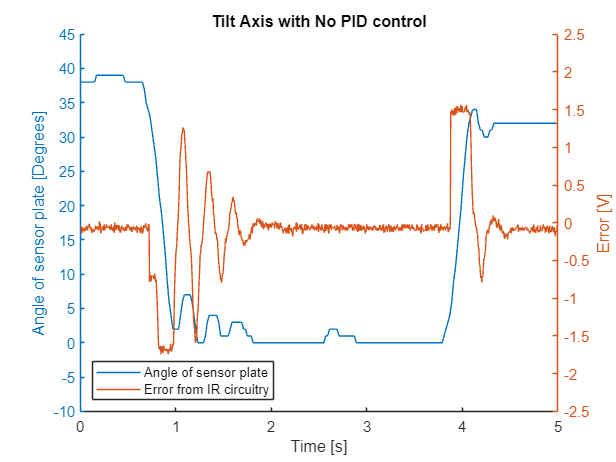


% Clear temporary variables
clear opts2

% Display results

array = table2array(motor_encoder_tilt_nopid);
array = (array(array(:,1) == 2, 2) + 203);

array = array(t_s:249+t_s, :);

hold on
yyaxis left            % Activate left y-axis
plot(T:2*T:length(array)*2*T, array)
ylabel('Angle of sensor plate [Degrees]')
ylim([-10 45])

yyaxis right           % Activate right y-axis
plot(scope_array(:,1)-2.6,scope_array(:,2))
ylabel('Error [V]');
ylim([-2.5 2.5])

xlabel('Time [s]')
legend({'Angle of sensor plate', 'Error from IR circuitry'},'Location','southwest')
title('Tilt Axis with No PID control');

hold off

## Clear temporary variables

clear all;
clf
clear opts

Fs = 100;           % Sampling frequency
T = 1/Fs;           % Sampling period
L = 10*Fs;          % Length of signal
t_s = 290;          % Encoder signal start time

# Import data from text file

## Set up the Import Options and import the data

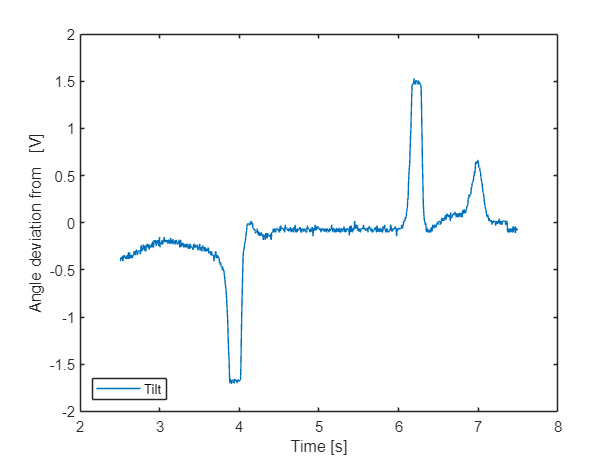

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_tilt_pid.csv", opts);
scoperb62(:,"xaxis") = scoperb62(:,"xaxis") + 10; % fix time
scoperb62(:,"VarName2") = scoperb62(:,"VarName2") - 1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3") - 1.65;

scope_array = table2array(scoperb62);
scope_array = scope_array((scope_array(:,1) > 2.5) & (scope_array(:,1) < 7.5),:); % fix time

plot(scope_array(:,1),scope_array(:,2))
hold on
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt'},'Location','southwest')

hold off

## Clear temporary variables

clear opts
clf

opts2 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ":";

% Specify column names and types
opts2.VariableNames = ["Motor", "Encoder Position"];
opts2.VariableTypes = ["double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Import the data
motor_encoder_tilt_pid = readtable("putty\motor_encoder_tilt_pid.log", opts2);

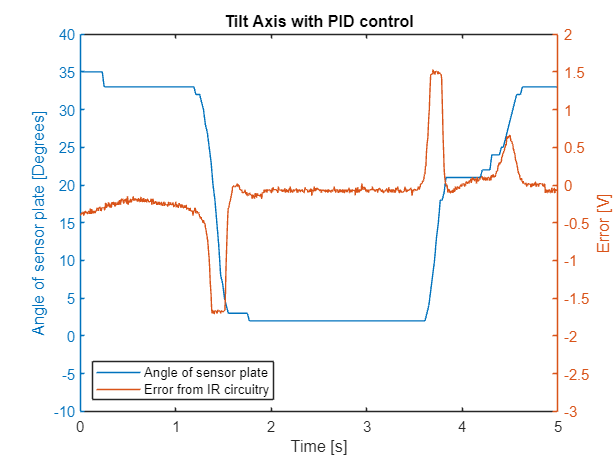


% Clear temporary variables
clear opts2

% Display results

array = table2array(motor_encoder_tilt_pid);
array = array(array(:,1) == 2, 2) + 160;

array = array(t_s:249+t_s, :);


yyaxis left            % Activate left y-axis
plot(T:2*T:length(array)*2*T, array)
ylabel('Angle of sensor plate [Degrees]')
ylim([-10 40])
yyaxis right           % Activate right y-axis
plot(scope_array(:,1)-2.5,scope_array(:,2))
ylabel('Error [V]');
ylim([-3 2])

xlabel('Time [s]')
legend({'Angle of sensor plate', 'Error from IR circuitry'},'Location','southwest')
title('Tilt Axis with PID control');
hold off

## Clear temporary variables

clear all;
clf
clear opts

Fs = 100;           % Sampling frequency
T = 1/Fs;           % Sampling period
L = 10*Fs;          % Length of signal
t_s = 1311;         % Encoder signal start time

# Import data from text file

## Set up the Import Options and import the data

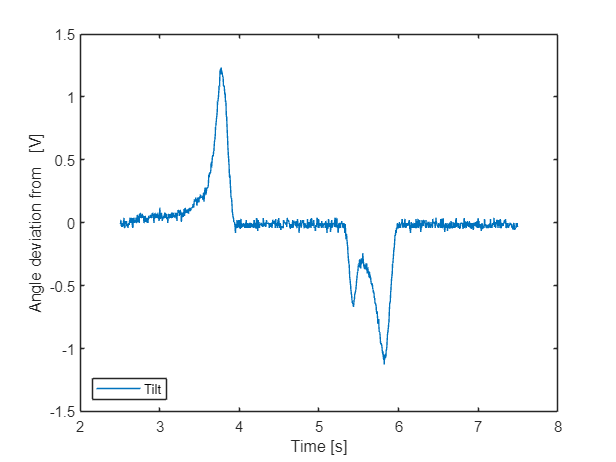

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_pan_nopid.csv", opts);
scoperb62(:,"xaxis") = scoperb62(:,"xaxis") + 10; % fix time
scoperb62(:,"VarName2") = scoperb62(:,"VarName2") - 1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3") - 1.65;

scope_array = table2array(scoperb62);
scope_array = scope_array((scope_array(:,1) > 2.5) & (scope_array(:,1) < 7.5),:); % fix time

plot(scope_array(:,1),scope_array(:,3))
hold on
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt'},'Location','southwest')

hold off

## Clear temporary variables

clear opts
clf

opts2 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ":";

% Specify column names and types
opts2.VariableNames = ["Motor", "Encoder Position"];
opts2.VariableTypes = ["double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Import the data
motor_encoder_tilt_nopid = readtable("putty\motor_encoder_pan_nopid.log", opts2);

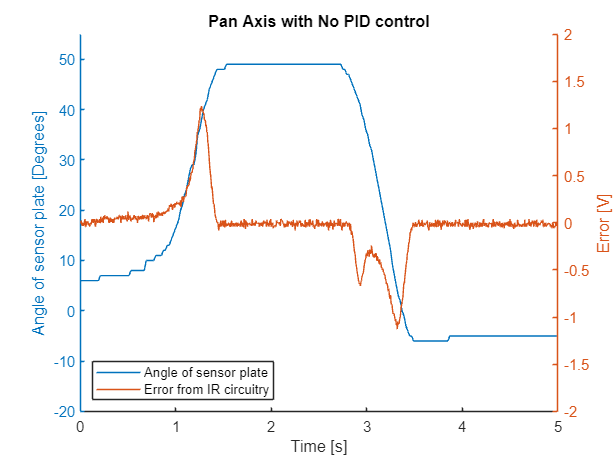


% Clear temporary variables
clear opts2

% Display results

array = table2array(motor_encoder_tilt_nopid);
array = (array(array(:,1) == 1, 2))*-1;
array = array(t_s:249+t_s, :);

hold on
yyaxis left            % Activate left y-axis
plot(T:2*T:length(array)*2*T, array)
ylabel('Angle of sensor plate [Degrees]')
ylim([-20 55])

yyaxis right           % Activate right y-axis
plot(scope_array(:,1)-2.5,scope_array(:,3))
ylabel('Error [V]');
ylim([-2 2])

xlabel('Time [s]')
legend({'Angle of sensor plate', 'Error from IR circuitry'},'Location','southwest')
title('Pan Axis with No PID control');

hold off

## Clear temporary variables

clear all;
clf
clear opts

Fs = 100;           % Sampling frequency
T = 1/Fs;           % Sampling period
L = 10*Fs;          % Length of signal
t_s = 22;           % Encoder signal start time

# Import data from text file

## Set up the Import Options and import the data

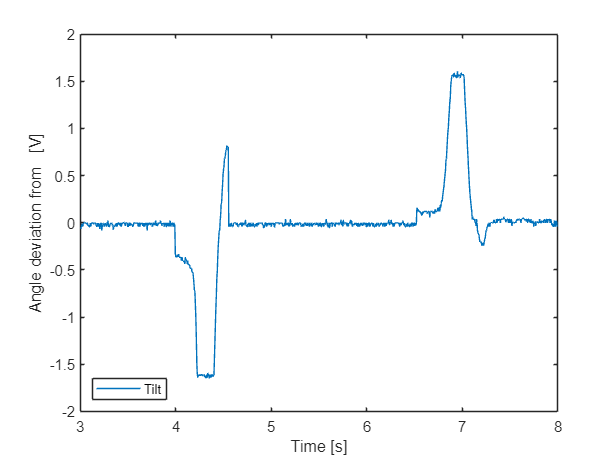

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_pan_pid.csv", opts);
scoperb62(:,"xaxis") = scoperb62(:,"xaxis") + 10; % fix time
scoperb62(:,"VarName2") = scoperb62(:,"VarName2") - 1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3") - 1.65;

scope_array = table2array(scoperb62);
scope_array = scope_array((scope_array(:,1) > 3) & (scope_array(:,1) < 8),:); % fix time

plot(scope_array(:,1),scope_array(:,3))
hold on
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt'},'Location','southwest')

hold off

## Clear temporary variables

clear opts
clf

opts2 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ":";

% Specify column names and types
opts2.VariableNames = ["Motor", "Encoder Position"];
opts2.VariableTypes = ["double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Import the data
motor_encoder_tilt_pid = readtable("putty\motor_encoder_pan_pid.log", opts2);

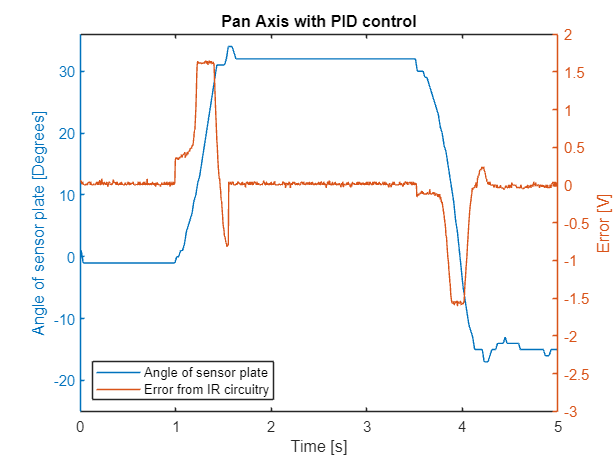


% Clear temporary variables
clear opts2

% Display results

array = table2array(motor_encoder_tilt_pid);
array = array(array(:,1) == 1, 2);

array = array(t_s:249+t_s, :);


yyaxis left            % Activate left y-axis
plot(T:2*T:length(array)*2*T, array)
ylabel('Angle of sensor plate [Degrees]')
ylim([-25 36])
yyaxis right           % Activate right y-axis
plot(scope_array(:,1)-3,scope_array(:,3)*-1)
ylabel('Error [V]');
ylim([-3 2])

xlabel('Time [s]')
legend({'Angle of sensor plate', 'Error from IR circuitry'},'Location','southwest')
title('Pan Axis with PID control');
hold off